# Eventos Matlab

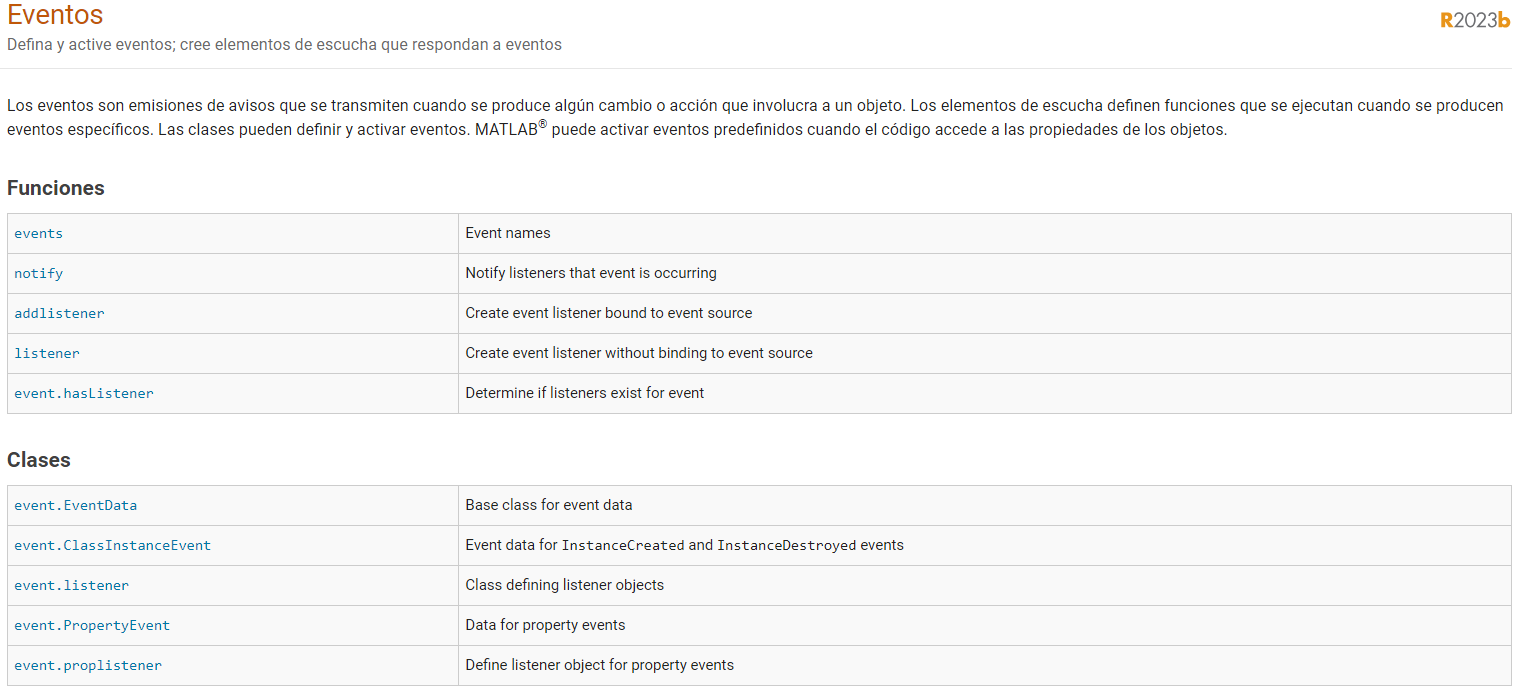

Ejemplo pelota:

function Pelota_Cayendo
ti=0;
tf=25;%++25++
x0=[10,0];
coef_restitucion=-0.9; %+++ -1 ++porque la pelota rebota y sube
opciones=odeset('Events',@eventos,'refine',500); %500 es efecto de la simulacion sea lento
xout=x0;
tout=ti;
xe=[];
te=[];
while ti<tf
    [t,x,tee,xee,iee]=ode45(@sistema,[ti tf],x0,opciones);
    tout = [tout; t(2:end)];
    xout = [xout; x(2:end,:)];
    ti=t(end);
    x0(1)=x(end,1);
    x0(2)=x(end,2)*coef_restitucion; %9.9 porque va disminuyendo la velocidad 
    
    te = [te; tee];
    xe = [xe; xee];
end
plot(tout,xout(:,1),'--',te,xe(:,1),'*g');
grid on;
%comet(tout,xout(:,1)); %Ver animación
xlabel('Tiempo [s]')
ylabel('Altura [m]')
end

function dx=sistema(t,x)
dx=zeros(2,1);
dx(1)=x(2);
dx(2)=-9.8; %menos porque la pelota cae
end

function [value,isterminal,direction]=eventos(t,x)
value=x(1);
isterminal=1;
direction=-1; %-1 cuando se cumple el evento, 
% 1 cuando no quiero que pare la simulación, 0 no me importa que haga
end 

# Buck Converter Por código.

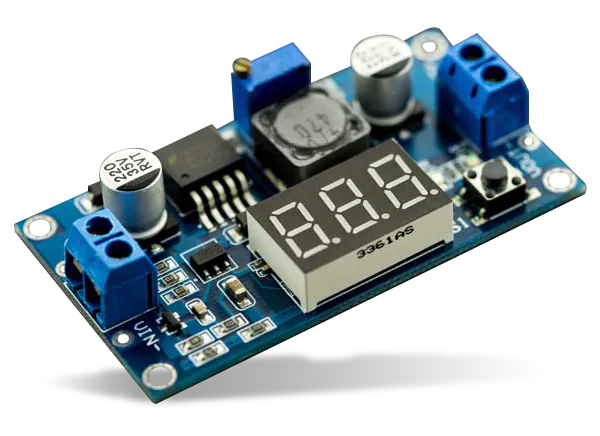

## Parámetros:

C = 10e-6      % Capacitancia Faradios.
L = 10e-3      % Inductancia Henrios.

C = 1.0000e-05

Vsource = 12     % Voltaje de fuente Voltios

L = 0.0100

Rload = 10        % Resistencia de carga OHmios

Vsource = 12

Vref = 5      % Voltaje de referencia Voltios

Rload = 10

Vh = 0.5      % Histeresis en volts

Vref = 5

Vh = 0.5000

% Condiciones iniciales
IL_ini = 0;      % Corriente inicial del inductor (A)
VC_ini = 0;      % Voltaje inicial del capacitor (V)

% Rango Duración de simulación en segundos.
tsim = [0 0.01]; % Tiempo de simulación

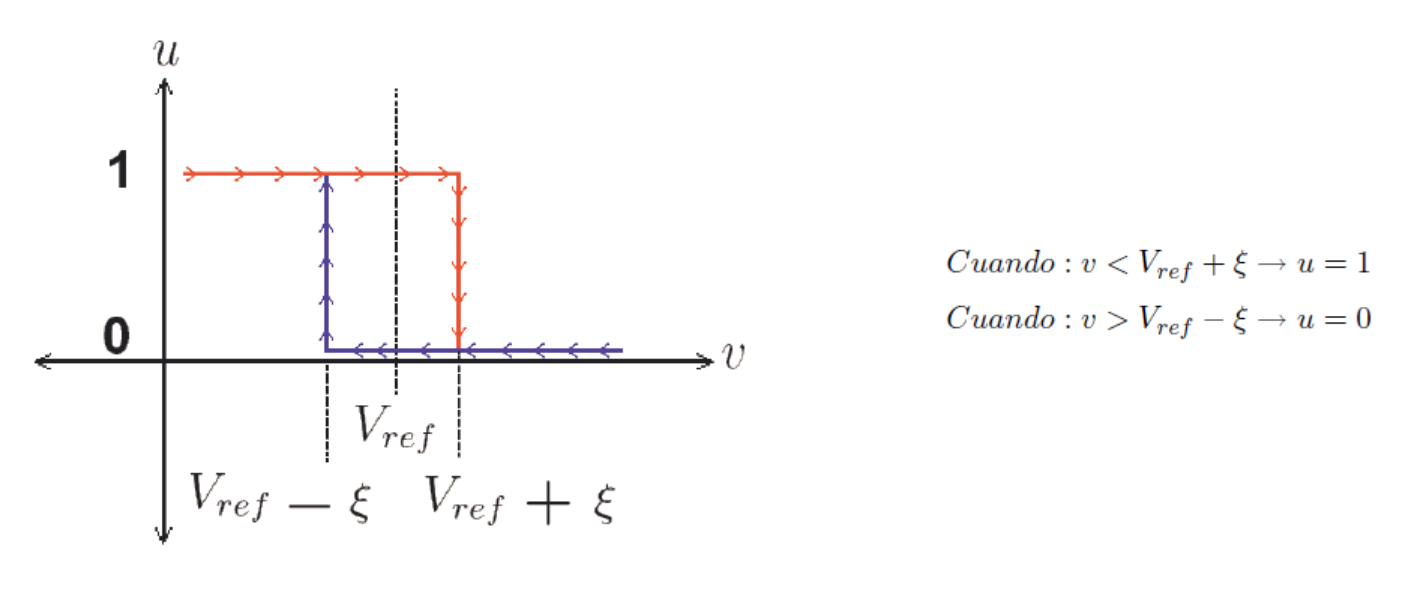

## Eventos

La función `eventsFcn` se utiliza para definir los eventos en la simulación.

Detección de cruze por límites de histéresis:

- `y(2) - (Vref + Vh/2)`: Representa la diferencia entre el voltaje del capacitor (`y(2)`) y el **límite** **superior** de histéresis (`Vref + Vh/2`).

- `y(2) - (Vref - Vh/2)`: Representa la diferencia entre el voltaje del capacitor (`y(2)`) y el **límite** **inferior** de histéresis (`Vref - Vh/2`).

`isterminal`:  establecen dos condiciones, [0; 0] para que simulación continue.

`direction`: Define la dirección en la que se deben detectar los eventos:

- `1` indica que se debe **detectar el evento** cuando el voltaje del capacitor cruza el **límite superior** de histéresis.

- `-1` indica que se debe detectar el evento cuando el voltaje del capacitor cruza el límite inferior de histéresis.

function [value, simuContinua, direccion] = eventsFcn(t, y, Vref, Vh)
    value = [y(2) - (Vref + Vh/2); y(2) - (Vref - Vh/2)];
    simuContinua = [0; 0]; %No se detiene en esos eventos.
    direccion = [1; -1]; 
end

## Sistema

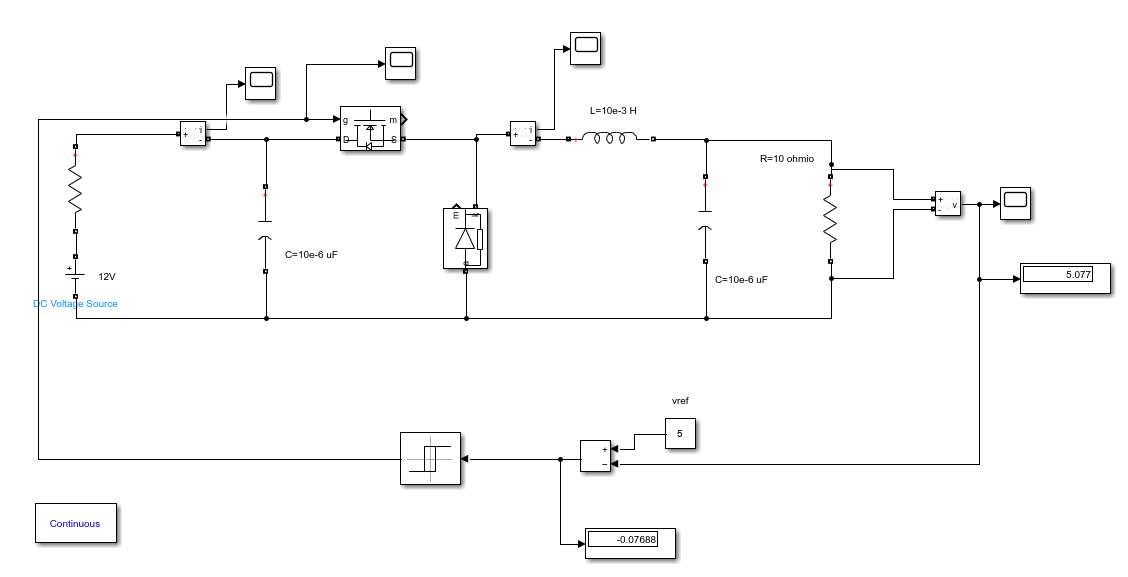

`La ``y`` es el v`ector de estado con dos componentes: 

- `y(1)` representa la corriente del inductor (`I_L`),

- `y(2)` representa el voltaje del capacitor (`V_C`).

**u** es el estado de interruptor.

function dydt = Circuitobuck(t, y, Vin, L, C, Rload, u)
    I_L = y(1);
    V_C = y(2);
    dydt = zeros(2,1);
    dydt(1) = (Vin * u - V_C) / L;  %Por Kirchooff.
    dydt(2) = (I_L - V_C / Rload) / C;
end

## ODE

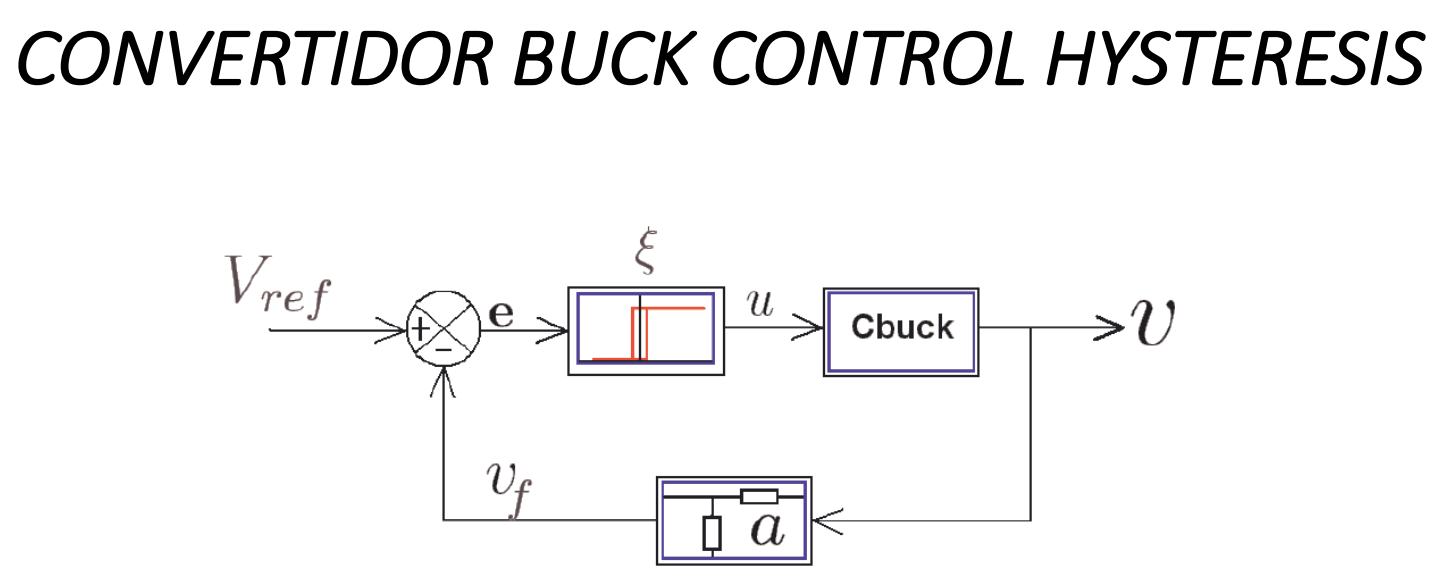

function dydt = buckODE(t, y, Vin, L, C, Rload, Vref, Vh)
    persistent u; %declara variable que retiene su valor entre llamadas de función.
    if isempty(u)
        u = 1; % Estado inicial Mosfeet en corto.
    end
    
    % Histeresis
    if y(2) >= Vref + Vh/2
        u = 0; % Circuito Abierto Mosfet                   u=0:[------*    *------]
    elseif y(2) <= Vref - Vh/2
        u = 1; % Circuito Cerrado Mosffet como conductor   u=1:[------*----*------]
    end
    
    % Llamada de función Dinámica del convertidor Buck
    dydt = Circuitobuck(t, y, Vin, L, C, Rload, u);
end

% Eventos ODE
ode_eventos = odeset('Events', @(t, y) eventsFcn(t, y, Vref, Vh), 'RelTol', 1e-6, 'AbsTol', 1e-6); %odeset() para crear o modificar estructura del solver().   RelTol() es tolerancia relatia, AbsTol() presición absoluta del solver.
[t, y] = ode45(@(t, y) buckODE(t, y, Vsource, L, C, Rload, Vref, Vh), tsim, [IL_ini, VC_ini], ode_eventos); %Resuelve ODE.

## Gráficas

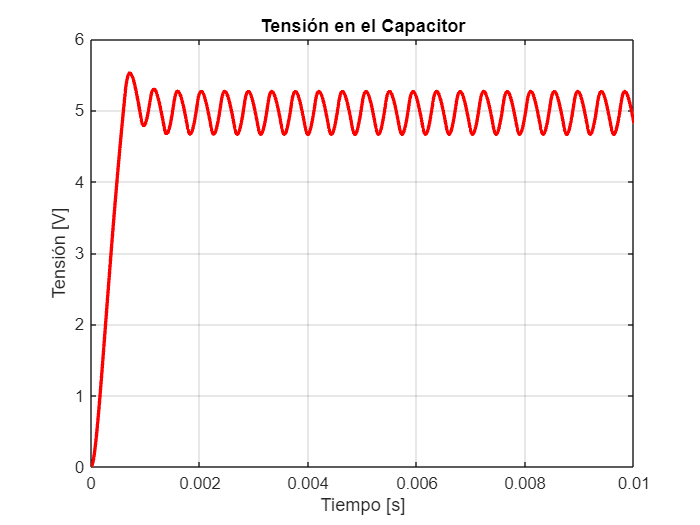

figure;
plot(t, y(:,2),'r', 'LineWidth', 2);
title('Tensión en el Capacitor');

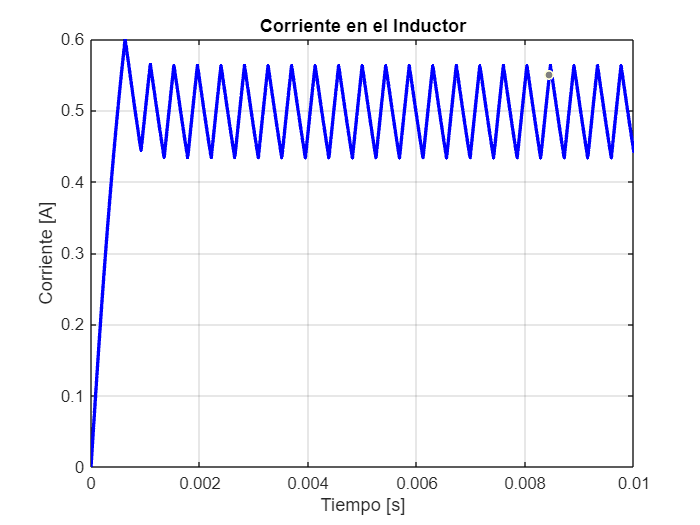

xlabel('Tiempo [s]'); ylabel('Tensión [V]');
grid on;
figure;
plot(t, y(:,1),'b', 'LineWidth', 2);
title('Corriente en el Inductor');

xlabel('Tiempo [s]'); ylabel('Corriente [A]');
grid on;

# Resultados Simulink.

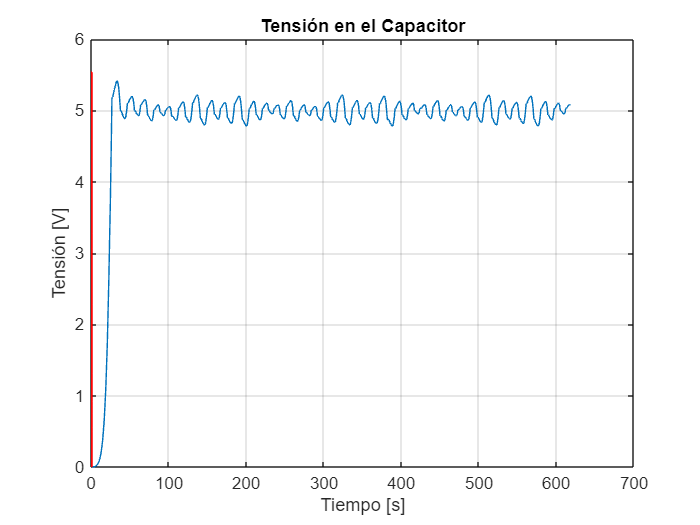

figure;
plot(out.ScopeData1_tension.signals.values)
title('Gráfica Tensión Salida')
xlabel('tiempo [s]')
ylabel('Tensión [v]')
grid on;
hold on

plot(t, y(:,2),'r', 'LineWidth', 2);
title('Tensión en el Capacitor');
xlabel('Tiempo [s]'); ylabel('Tensión [V]');
grid on;
hold off;

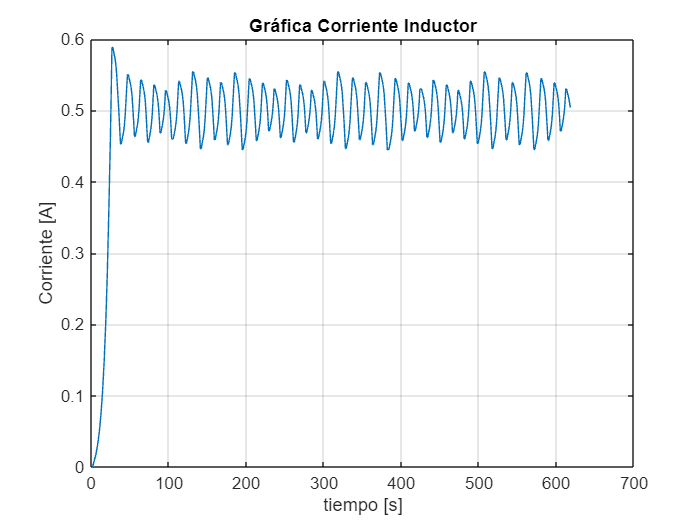

%===========
figure;
plot(out.ScopeData1_corriente.signals.values)
title('Gráfica Corriente Inductor')
xlabel('tiempo [s]')
ylabel('Corriente [A]')
grid on;
hold on

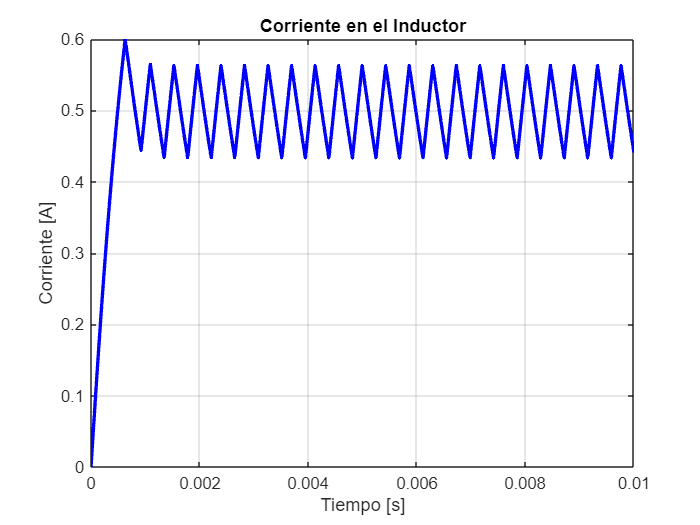

figure;
plot(t, y(:,1),'b', 'LineWidth', 2);
title('Corriente en el Inductor');
xlabel('Tiempo [s]'); ylabel('Corriente [A]');
grid on;
hold off;